# 案例：用 Matlab 绘制高质量的论文插图 2

## 伪彩图+投影图

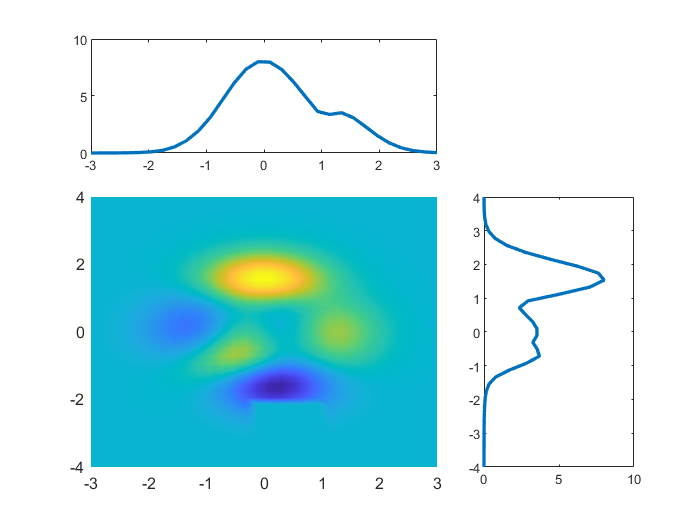

clear;clc;close all;
x = linspace(-3, 3, 30);
y = linspace(-4, 4, 40);
[X, Y] = meshgrid(x, y);
Z = peaks(X, Y);
Z(5:10, 15:20) = 0;
z1 = max(Z);
z2 = max(Z, [], 2);
figure;
subplot(3, 3, [1, 2]);
plot(x, z1, 'LineWidth', 2);
subplot(3, 3, [6, 9]);
plot(z2, y, 'LineWidth', 2);
subplot(3, 3, [4, 5, 7, 8]);
surf(x, y, Z);
xlim([-3, 3]);
ylim([-4, 4]);
view(0, 90);
shading interp

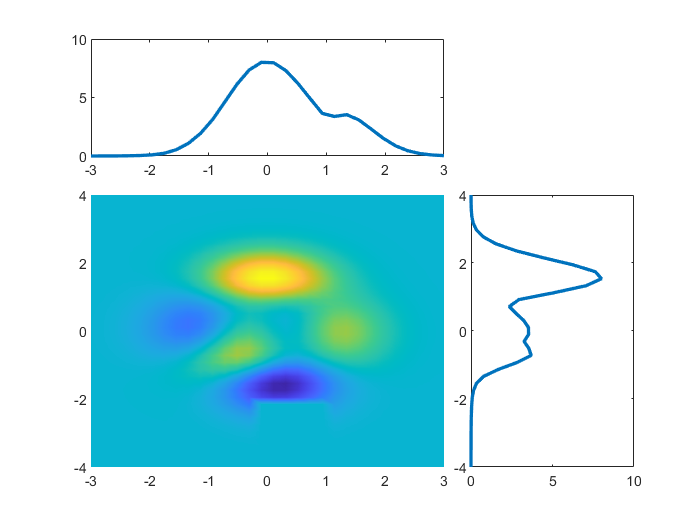

figure;
% 3*3 布局
tiledlayout(3, 3, 'TileSpacing', 'Compact');
% 占据 1*2，也就是 1 2
nexttile([1, 2]);
plot(x, z1, 'LineWidth', 2);
% 从第 6 个开始，占据 2*1，也就是 6 和 9
nexttile(6, [2, 1]);
plot(z2, y, 'LineWidth', 2);
% 从第 4 个开始，占据 2*2，也就是 4 5 7 8
nexttile(4, [2, 2]);
surf(x, y, Z);
xlim([-3, 3]);
ylim([-4, 4]);
view(0, 90);
shading interp

## 条形分布图

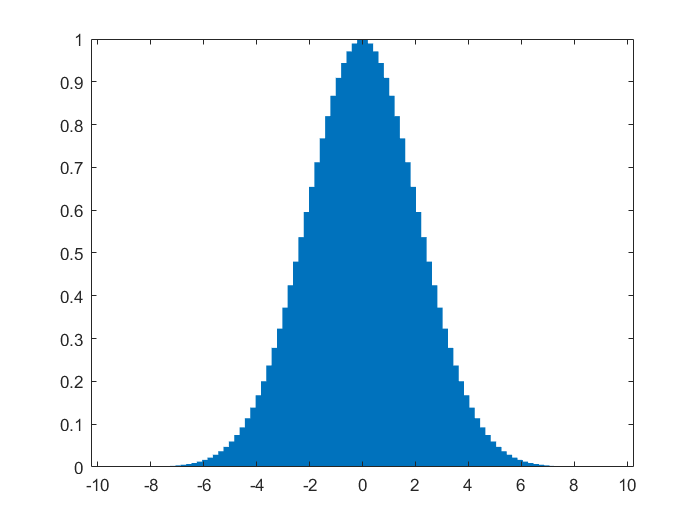

clear;clc;
x = linspace(-10, 10, 100);
y = gauss(100, 5) ; 
figure;
% 设置边缘颜色和宽度
bar(x, y, 'EdgeColor', 'none', 'BarWidth', 1);

## 热图

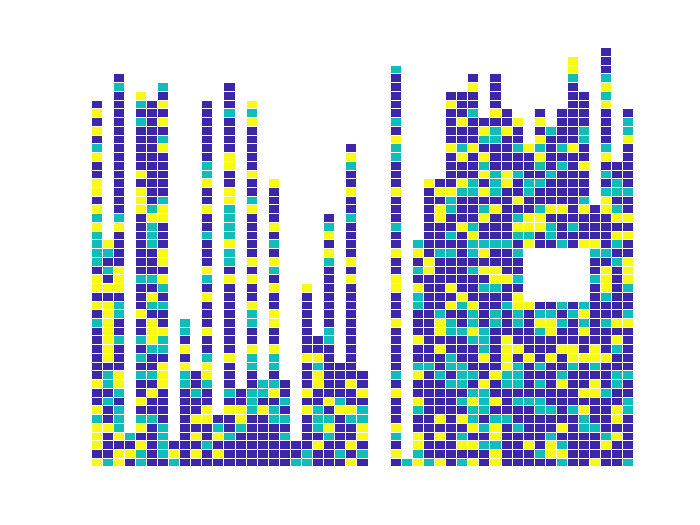

clear;clc;
z = rand(50);
z(z >= 0.0 & z < 0.6) = 0.5;
z(z >= 0.6 & z < 0.8) = 0.7;
z(z >= 0.8 & z <= 1) = 0.9;

for i = 1:30
    z(randi(50, 1, 1) : end, i) = nan;
end
for i = 31:50
    z(30 + randi(20, 1, 1) : end, i) = nan;
end
z(20:25, 40:45) = nan;
figure;
% ax = surf(z);
ax = pcolor(z);
view(0, 90);
ax.EdgeColor = [1 1 1];
axis off

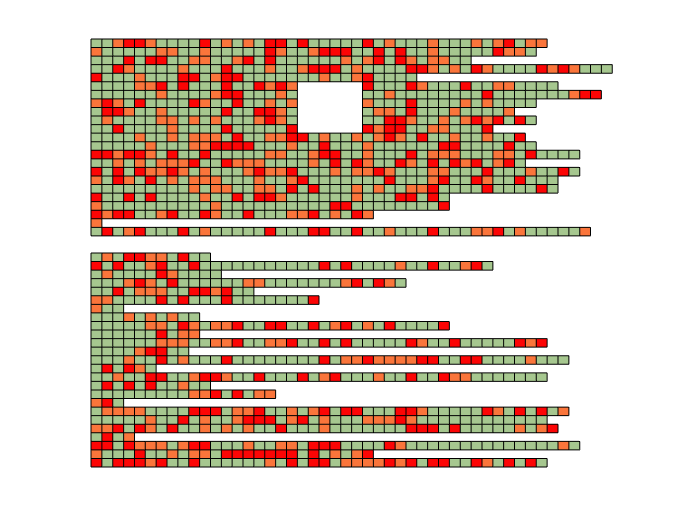

figure;
for i = 1:50
    for j = 1:50
        if ~isnan(z(i, j))
            x = [i - 1, i, i, i - 1];
            y = [j - 1, j - 1, j, j];
            c1 = 'w';
            c2 = 'w';
            if z(i, j) >= 0.1
                c1 = 'black';
                c2 = [0.65, 0.78, 0.56];
                if z(i, j) >= 0.6
                    c2 = [0.98, 0.46, 0.23];
                    if z(i, j) >= 0.8
                        c2 = [0.99, 0.02, 0.02];
                    end
                end
            end
            patch(x, y, c2, 'EdgeColor', c1);
        end 
    end
end
axis off

## 分子模型图

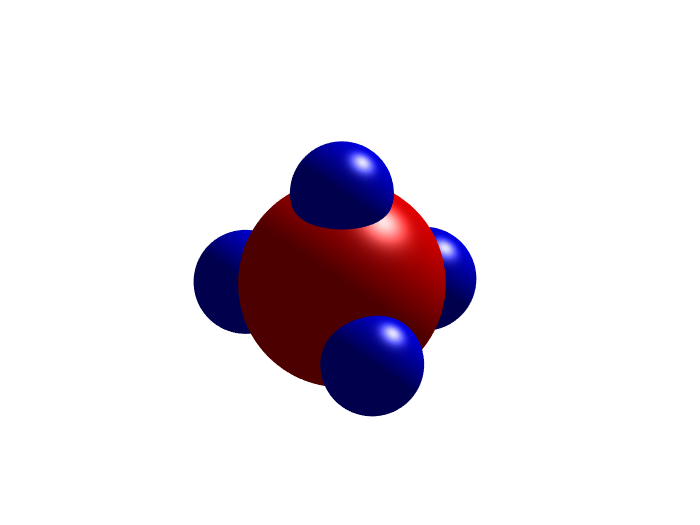

clear;clc;
% 球面的坐标信息，为了看起来平滑一点，给到 100
[x, y, z] = sphere(100);
% C 大小
C = 10; 
% H 大小
H = 5;
figure;
% 大球
surf(C*x, C*y, C*z, 'FaceColor', 'red', 'EdgeColor', 'none')
hold on 
% 四个小球，都偏离一点位置，准确的位置需要计算，这里演示一个大概位置
surf(H*x, H*y, H*z + 10, 'FaceColor', 'blue', 'EdgeColor', 'none');
surf(H*x + 10, H*y, H*z - 3, 'FaceColor', 'blue', 'EdgeColor', 'none');
surf(H*x - 4, H*y - 10, H*z - 3, 'FaceColor', 'blue', 'EdgeColor', 'none');
surf(H*x - 4, H*y + 10, H*z - 3, 'FaceColor', 'blue', 'EdgeColor', 'none');
% 坐标轴设置
axis equal off
% 光源，看起来更有立体感
light
lighting gouraud

## 分形图

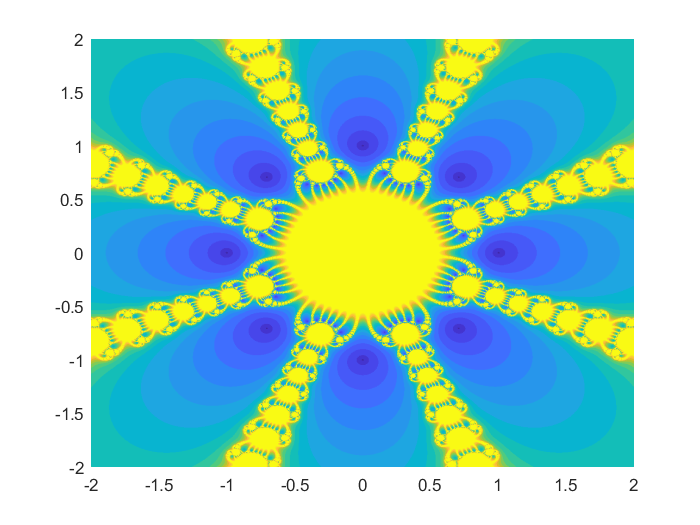

clear;clc;
n = 1000;
m = 1000;
f = @(z) z^8 - 1;
df = @(z) 8*z^7;
[X, Y] = meshgrid(linspace(-2, 2, n), linspace(-2, 2, m));
A = nan(n, m);
for i = 1:n
    for j = 1:m
        z0 = X(i, j) + 1i*Y(i, j);
        % Newton-Raphson
        z = z0;
        ite = 0;
        fz = f(z);
        while abs(fz) > 1e-6 && ite < 20
            z = z - f(z)/df(z); 
            fz = f(z);
            ite = ite + 1;
        end
        A(i, j) = ite;
    end
end
figure;
pcolor(X, Y, A);
% hold on
% plot([1, -1, 0, 0], [0, 0, 1, -1], '.k', 'MarkerSize', 20);
% hold off
shading flat
axis tight manual 

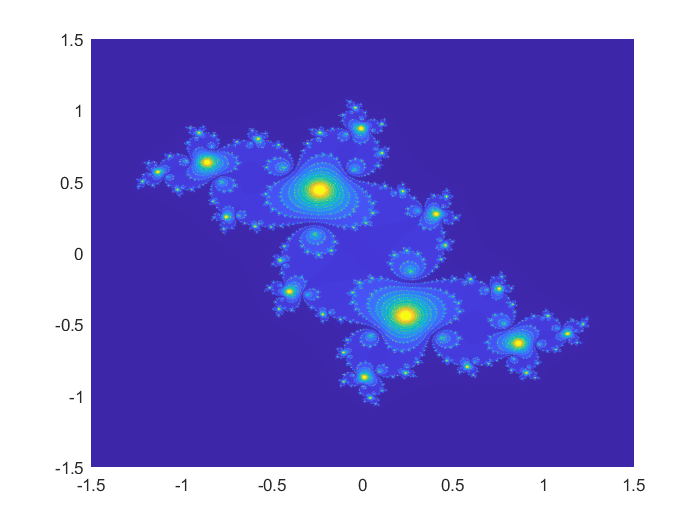

% xlim([-0.5, 0]);
% ylim([0.5, 1]);
% 保存成视频
% set(gca, 'nextplot', 'replacechildren'); 
% v = VideoWriter('NRfractal.avi');
% open(v);
% for k = 1:20 
%     pcolor(X, Y, A);
%     shading flat
%     xlim([-2*(1-k/25), 2*(1-k/25)]);
%     ylim([-2*(1-k/25), 2*(1-k/25)]);
%     frame = getframe(gcf);
%     writeVideo(v, frame);
% end

% (-0.19, 0.6557)
% (-0.1, 0.651)
% zx = zx*zx - zy*zy + cx
% zy = 2*zx*zy+cy
c = - 0.1 + 1i*0.651;
radius = 32;
[X, Y] = meshgrid(linspace(-1.5, 1.5, n), linspace(-1.5, 1.5, m));
A = nan(n, m);
for i = 1:n
    for j = 1:m
        z = X(i, j) + 1i*Y(i, j);
        % Julia
        for ite = 1:1000
            z = (z*z + c) ;
            if abs(z) > radius
                break;
            end
        end
        A(i, j) = ite;
    end
end
figure;
pcolor(X, Y, A);
shading flat
axis tight manual

## 曲线斜线填充

[https://zhuanlan.zhihu.com/p/435763835](https://zhuanlan.zhihu.com/p/435763835)

## 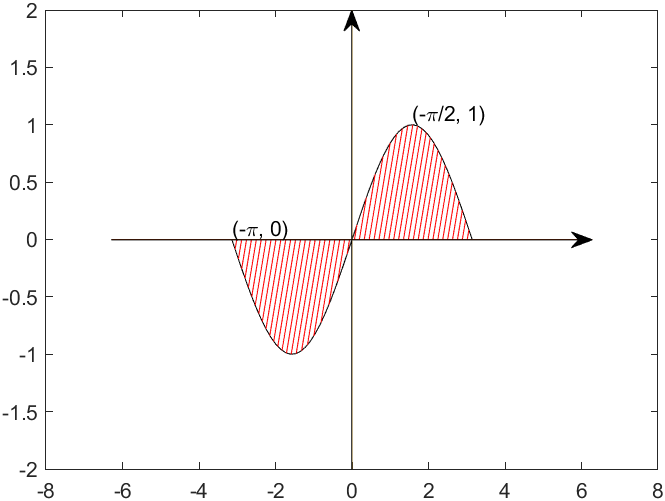

## 曲面贴图

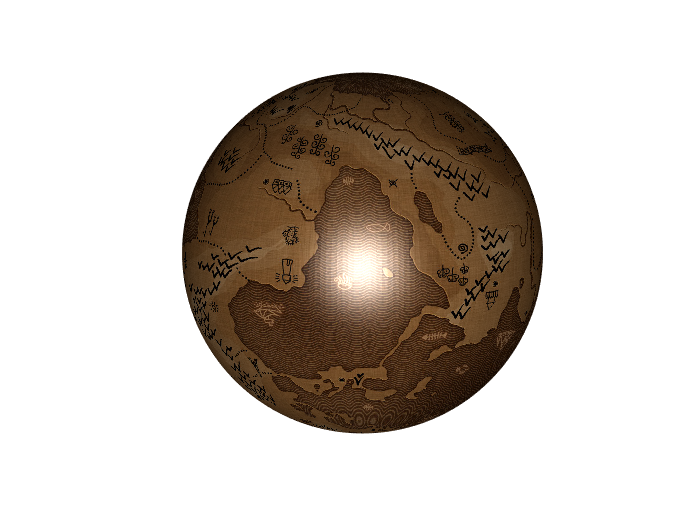

clear;clc;
figure;
% 读取地图文件
image = imread('World.jpg'); 
% 生成一个球面数据
[x, y, z] = sphere(200);
% 绘制球体
p = surf(x, y, z); 
% 去网格线
shading interp;
p.CData = image; 
% 纹理贴图
p.FaceColor = "texturemap"; 
axis equal;
axis off
% 光源，看起来更有立体感
% light
% lighting gouraud
% 光源颜色
handle = light('Color', [1 1 1]);
t = 0;
while t < 100
    t = t + 1;
    view([t 10]);
    lightangle(handle, t, 0);
    pause(0.01);
end